# Problem 3-1

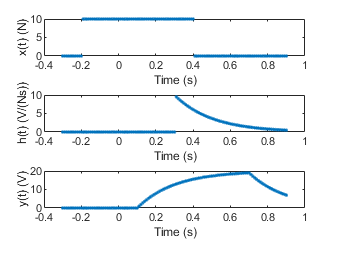

% 3-1e
t_start = -0.3;
t_end = 0.9;
delta = 0.01;
t = t_start:delta:t_end;

x_start = -0.2;
x_end = 0.4;

x = [zeros(1, length(t_start:delta:x_start)),...
    repmat(10, [1,length(x_start+delta:delta:x_end)]),...
    zeros(1, length(x_end+delta:delta:t_end))];

h_start = 0.3;
t_h = h_start+delta:delta:t_end;
h = [zeros(1, length(t_start:delta:h_start)),...
    10*exp(-5.*(t_h-0.3))];

y_t1 = 0.1; % First transition point of y
y_t2 = 0.7; % Second transition point of y
t_y1 = t_start:delta:y_t1;
t_y2 = y_t1+delta:delta:y_t2;
t_y3 = y_t2+delta:delta:t_end;

y_1 = zeros(1,length(t_y1));
y_2 = 20 - 20*exp(-5.*(t_y2-0.1));
y_3 = 20*exp(-5.*(t_y3-0.7)) - 20*exp(-5.*(t_y3-0.1));
y = [y_1 y_2 y_3];

figure;
subplot(3,1,1)
plot(t,x,'.');
xlabel('Time (s)')
ylabel('x(t) (N)')

subplot(3,1,2)
plot(t,h,'.');
xlabel('Time (s)')
ylabel('h(t) (V/(Ns))')

subplot(3,1,3)
plot(t,y,'.');
xlabel('Time (s)')
ylabel('y(t) (V)')

## Problem 3-2

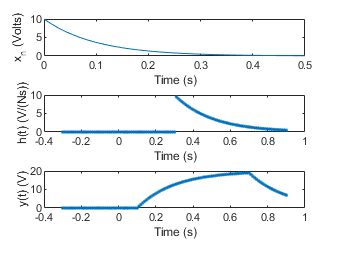

% 3-2i
clear

alpha = 10;
A = 10;
df = 0.01;
f_max = 40;
f_s = 1000;
delta = 1/f_s;
f = 0:df:f_max;
t_1 = 0:delta:0.5;
t_2 = 0:delta:0.2;

% Part (i)
n1 = 0:length(t_1)-1;
n2 = 0:length(t_2)-1;
x_n = @(n) A.*exp(-alpha*delta.*n);
x_n1 = x_n(n1);
x_n2 = x_n(n2);

figure(1);
subplot(3,2,[1 2])
plot(t_1, x_n1)
xlabel('Time (s)')
ylabel('x_n (Volts)')
ylim([0, A])

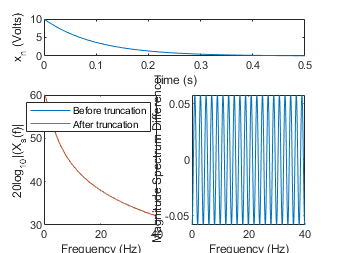


figure(2);
subplot(3,2,[1 2])
plot(t_2, x_n2)
xlabel('Time (s)')
ylabel('x_n (Volts)')
ylim([0, A])


% Part (ii)
X_inf = A./(1-exp(-(alpha+1j*2*pi.*f)*delta));
X_N = @(n) A.*(1-exp(-(alpha+1j*2*pi.*f)*delta*length(n)))./(1-exp(-(alpha+1j*2*pi.*f)*delta));
X_N1 = X_N(n1);
X_N2 = X_N(n2);

figure(1)
subplot(3,2,[3 5])
plot(f, 20*log10(abs(X_inf)), f,20*log10(abs(X_N1)));
legend('Before truncation', 'After truncation')
xlabel('Frequency (Hz)')
ylabel('20log_{10}|(X_s(f)|')

figure(2)
subplot(3,2,[3 5])
plot(f, 20*log10(abs(X_inf)),f,20*log10(abs(X_N2)))
legend('Before truncation', 'After truncation')
xlabel('Frequency (Hz)')
ylabel('20log_{10}|(X_s(f)|')

% Part (iii)

figure(1)
subplot(3,2,[4 6])
plot(f, 20*log10(abs(X_N1))-20*log10(abs(X_inf)));
xlabel('Frequency (Hz)')
ylabel('Magnitude Spectrum Difference')

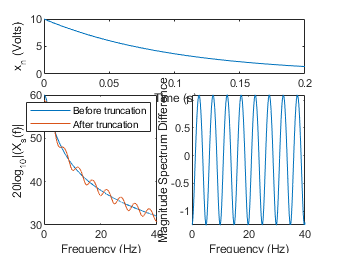


figure(2)
subplot(3,2,[4 6])
plot(f, 20*log10(abs(X_N2))-20*log10(abs(X_inf)))
xlabel('Frequency (Hz)')
ylabel('Magnitude Spectrum Difference')

(3-2j) A larger t_0 reduces the difference between the spectrum before truncation and after truncation. Larger sampling rates increase the magnitude of X_s(f).

## Problem 3-3

Problems 3-3c and 3-3d are in the function section.

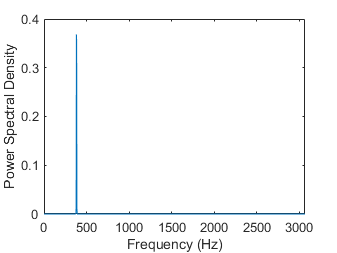

% Problem 3-3e
clear;
A = 3;
wave_freq = 2403; % rad/s
f_s = 2048; % samples/s
N = 2048; % sampling for 1s
dt = 1/f_s;

x = A*sin(wave_freq*dt*(0:N-1));

[f_hann, S_hat_hann, ~, ~] = psd_estimator(x, N, 'hann', f_s);

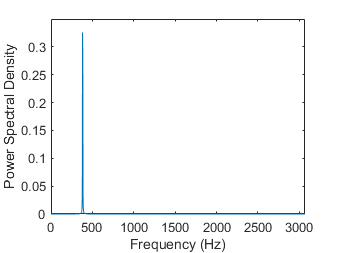

[f_rect, S_hat_rect, ~, ~] = psd_estimator(x, N, 'rect', f_s);

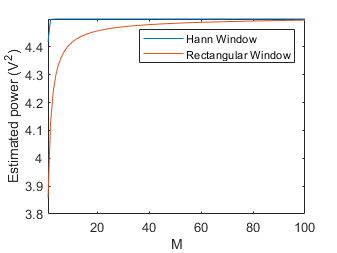


M = 1:100;
P_hann = zeros(max(M),1);
P_rect = zeros(max(M),1);

for i = M
    P_hann(i) = power_integrator(f_hann, S_hat_hann, 382, i, N, f_s);
    P_rect(i) = power_integrator(f_rect, S_hat_rect, 382, i, N, f_s);
end

figure;
plot(M,P_hann, M, P_rect)
xlim([1 max(M)])
xlabel('M')
ylabel('Estimated power (V^2)')
legend('Hann Window', 'Rectangular Window')

M_required for a Hann window is 2, while M_required for a rectangular window is around 20.

function [f, S_hat, N, f_s] = psd_estimator(x, N, window, f_s)

% Problem 3-3c

delta = 1/f_s;
T = N*delta;

% Using only N points in the signal
x = x(1:N);

if strcmpi(window, 'hann')
    w = 0.5*cos(2*pi.*(-N/2:N/2-1)*delta/T)+0.5;
    wcomp = 0.375;
elseif strcmpi(window, 'rect')
    w = ones(1,N);
    wcomp = 1;
end

% Apply window to vector
x_T = x.*w;

% Obtain Fourier transform of vector
X_k = fft(x_T, N);

f = 0:(f_s/N):0.5*f_s-1;
S_hat = (abs(delta.*X_k).^2./(N*delta*wcomp));
S_hat = S_hat(1:N/2);

figure;
plot(f, S_hat)
xlabel('Frequency (Hz)')
ylabel('Power Spectral Density')

end

function P = power_integrator(f, S_hat, peak_loc, M, N, f_s)
% Problem 3-3d

[~, peak_ind] = min(abs(f-peak_loc));
ind_vector = peak_ind-M:peak_ind+M;

P = 2*sum(S_hat(ind_vector))*f_s/N;

end